# Illustrate color channel correlations

Analysis of the space-color correlations, following Hel-Or's 1999 paper at HP Labs.  We read in a nice image

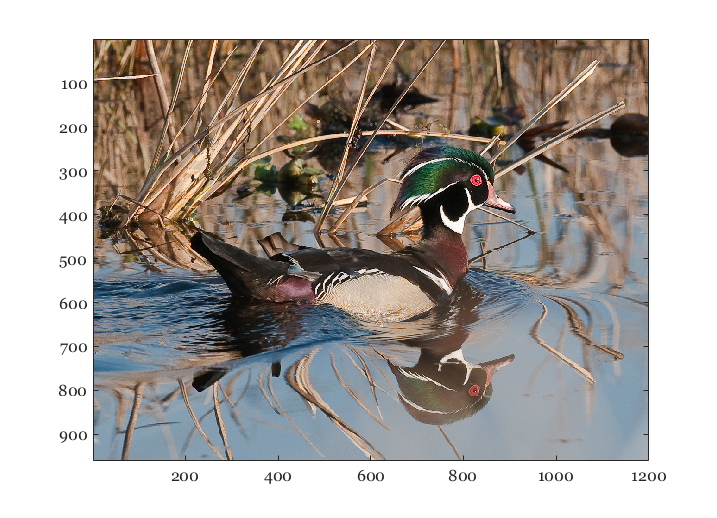

img = imread('sparksWoodDuckExtra.bmp');
vcNewGraphWin; imagesc(img);

## Extract the color channels and plot the pointwise correlation

These are correlated, but not perfectly by any means.  Looks a bit promising.

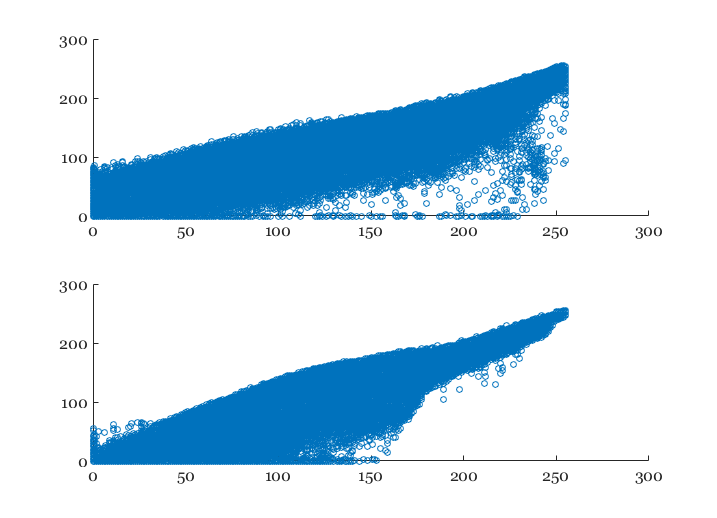

R = img(:,:,1); G = img(:,:,2); B = img(:,:,3);
vcNewGraphWin; 
subplot(2,1,1); scatter(R(:),G(:));
subplot(2,1,2); scatter(G(:),B(:));

## Compute the x-derivative and plot the correlation

When we take the spatial 

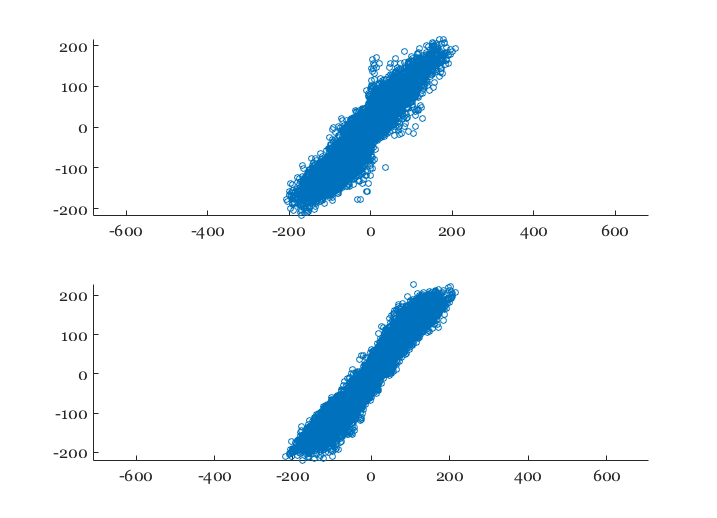

dRx = conv2(R,[1 -1],'same');
dGx = conv2(G,[1 -1],'same');
dBx = conv2(B,[1 -1],'same');

vcNewGraphWin; 
subplot(2,1,1); scatter(dRx(:),dGx(:)); axis equal
subplot(2,1,2); scatter(dGx(:),dBx(:)); axis equal

## Now the y-derivative

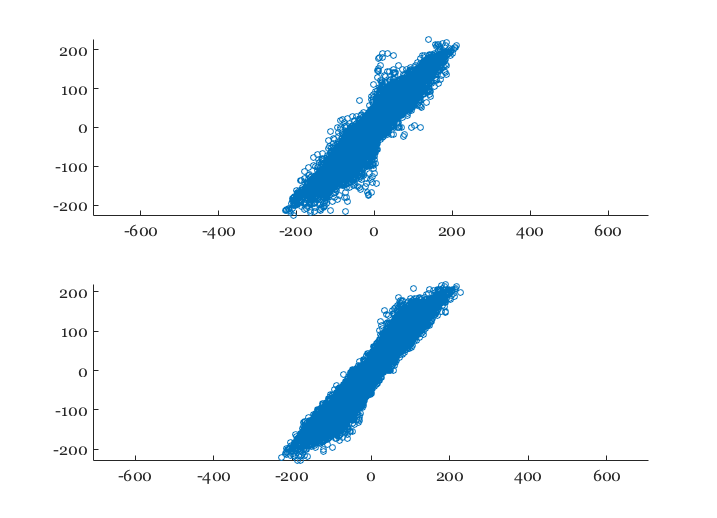

dRy = conv2(R,[1 -1]','same');
dGy = conv2(G,[1 -1]','same');
dBy = conv2(B,[1 -1]','same');

vcNewGraphWin; 
subplot(2,1,1); scatter(dRy(:),dGy(:)); axis equal
subplot(2,1,2); scatter(dGy(:),dBy(:)); axis equal

## Read an image and process through a camera

s = sceneFromFile('FruitMCC_6500.tif','rgb');

s = sceneSet(s,'fov',20);

camera = cameraCreate;

Camera from default oi,sensor and ip
Interpolating display SPD for consistency with new wave.


camera = cameraCompute(camera,s);

Extrapolating lens transmittance with 1's


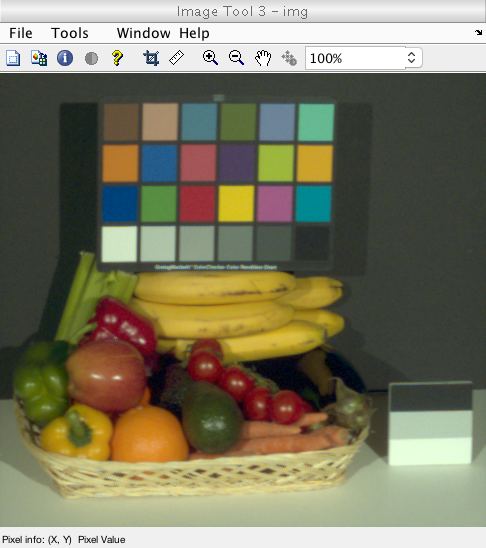

img = cameraGet(camera,'ip data srgb');
% cameraWindow(camera,'ip');
imtool(img);

## X-derivative correlations

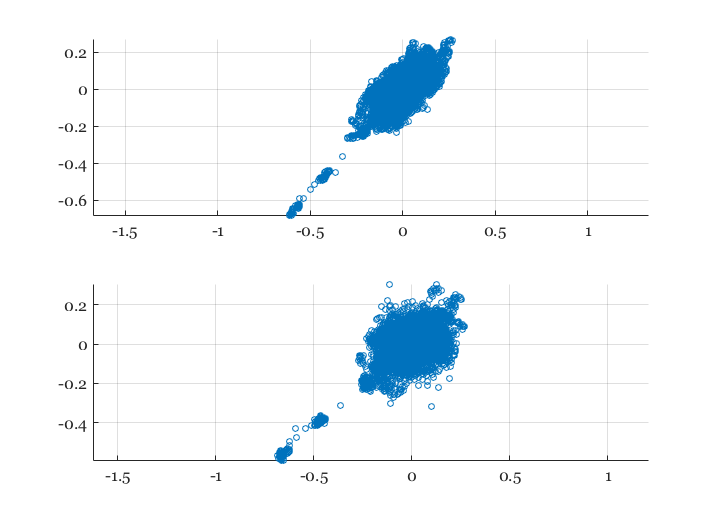

R = img(:,:,1); G = img(:,:,2); B = img(:,:,3);
dRx = conv2(R,[1 -1],'same');
dGx = conv2(G,[1 -1],'same');
dBx = conv2(B,[1 -1],'same');

vcNewGraphWin; 
subplot(2,1,1); scatter(dRx(:),dGx(:)); axis equal; grid on
subplot(2,1,2); scatter(dGx(:),dBx(:)); axis equal; grid on

## Y-derivative correlations 

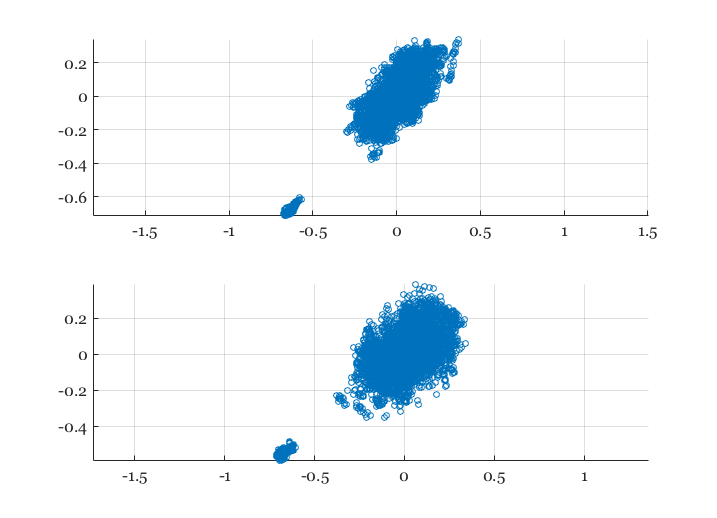

dRy = conv2(R,[1 -1]','same');
dGy = conv2(G,[1 -1]','same');
dBy = conv2(B,[1 -1]','same');


vcNewGraphWin; 
subplot(2,1,1); scatter(dRy(:),dGy(:)); axis equal; grid on
subplot(2,1,2); scatter(dGy(:),dBy(:)); axis equal; grid on

## The derivative images

vcNewGraphWin([],'tall');

ans =   Figure (22: ISET GraphWin) with properties:

      Number: 22
        Name: 'ISET GraphWin'
       Color: [1 1 1]
    Position: [0.0070 0.0550 0.2800 0.8500]
       Units: 'normalized'

  Show all properties


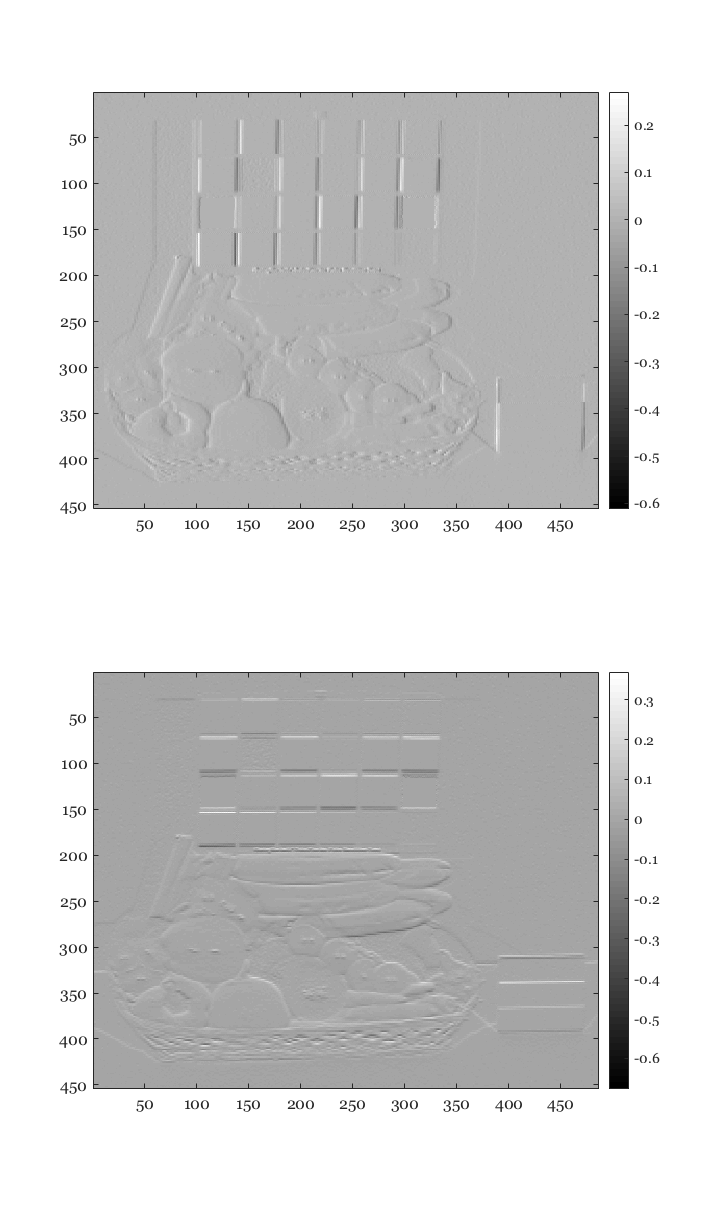

subplot(2,1,1); imagesc(dRx); colormap(gray); colorbar;
subplot(2,1,2); imagesc(dRy); colormap(gray); colorbar;